# Logic rẽ nhánh

[Menu menu chính](matlab:open('MainMenu.mlx'))

Máy tính phải được nói rõ ràng làm thế nào để đưa ra quyết định. Một loại quyết định phổ biến trong lập trình máy tính là một quyết định chi nhánh. Có một tuyên bố logic kiểm soát các đường dẫn nào có thể thông qua mã sẽ được theo dõi dựa trên trạng thái của các đầu vào. Một mô tả phổ biến về logic nhánh là biểu đồ dòng chảy, nhưng phân nhánh cũng có thể mô tả các tùy chọn có sẵn trong việc điều hướng một mê cung.

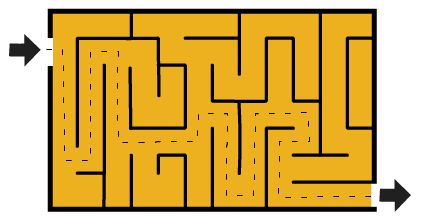

Các nhánh cho phép bạn tạo mã linh hoạt có thể phản ứng với các điều kiện thay đổi.

**Trước khi bạn bắt đầu:**

Tập lệnh trực tiếp này được dự định sẽ được sử dụng với mã hiển thị và đầu ra nội tuyến. TRÊN  **View** tab của công cụ MATLAB, trong **View** section, chọn **Output Inline**. Thay phiên, chọn **Output inline **Sử dụng biểu tượng   Ở phía trên bên phải của Live Editor pane.

Tương tác với tập lệnh trực tiếp này sẽ xây dựng một số quen thuộc với MATLAB, vì các khái niệm và lệnh được giới thiệu cùng nhau, nhưng một số quen thuộc với môi trường biên tập trực tiếp đã được giới thiệu trong [Giới thiệu.MLX](matlab:open('./Introduction.mlx')). Một bản tóm tắt ngắn gọn về các công cụ, mẹo và đề xuất từ ��mỗi tập lệnh được thu thập [Thu thập các mẹo chuyên nghiệp](matlab:open('./CollectedProTips.mlx'))

Để có trải nghiệm tối ưu, hãy làm theo các hướng dẫn và các bước trong chuỗi đã cho. Chỉ tiến hành một phần mới sau khi hoàn thành phần trước, bao gồm cả chạy tất cả các khối mã.

## Rẽ nhánh

Để điều hướng thế giới, bạn phải đưa ra lựa chọn thường xuyên. Có lẽ bạn đã đến một góc và bạn phải chọn giữa việc đi thẳng hoặc rẽ vào một con đường mới. Làm thế nào bạn sẽ đưa ra quyết định đó?

Mã phân nhánh thường được hiển thị với cấu trúc cây, chẳng hạn như được mô tả ở đây. Chạy khối mã này bằng cách nhấp vào  nút **Run Section** trong **Live Editor** tab.

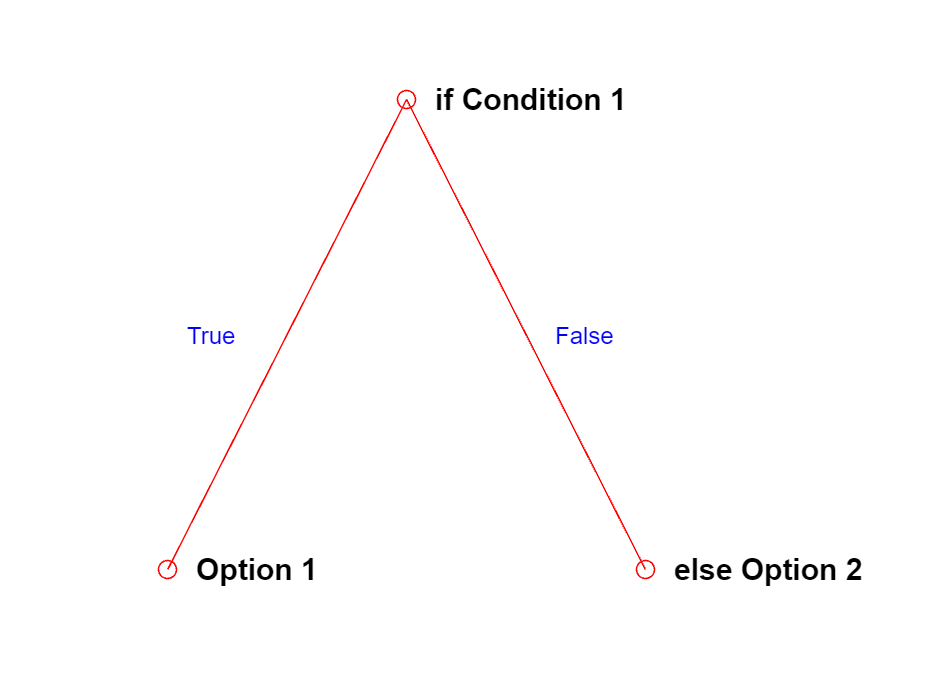

DrawIfThenTree(2)

  **Pro-tip.**Nếu bạn thà dán vào bàn phím hơn là sử dụng chuột để chạy các khối mã, bạn có thể chạy các khối mã trong phần hiện được chọn bằng cách nhập Ctrl-enter với nhau.

### rẽ nhánh if/else 

Loại phân nhánh nhị phân này được mô tả bởi `DrawIfThenTree(n) `Mô tả một loạt các lựa chọn đúng/sai xác định một đường dẫn qua cây nhị phân từ gốc đến lá. Ở mỗi nút có một điều kiện đúng/sai để kiểm tra. Kết quả của từng điều kiện xác định cạnh tiếp theo để theo chỉ định một tùy chọn cụ thể. Số `n `Chỉ định số lượng tùy chọn.

  **Thử**

- Phác thảo cây mà bạn mong đợi cho số lượng lớn hơn các tùy chọn, ví dụ: với `n=3` and/or `n=4` and/or `n=5`. Sau đó chạy`Drawifthentree (n)`. Các biểu đồ có khớp không?

- Điều gì xảy ra nếu `n = 1`? Hoặc nếu `n = 10`? Bạn sẽ cải thiện mã này trong Bài tập 2

- Mã ghi sẽ thực thi `disp("Hello, world!") `nếu như `GreetingChoice == "arriving" `và sẽ thực thi `disp("Goodbye, world!")` nếu như `GreetingChoice = "leaving"`. Sau đó chạy nó nhiều lần để thấy rằng mã theo các đường dẫn khác nhau dựa trên giá trị được tạo ngẫu nhiên của `greet`

Options = ["arriving" "leaving"];

GreetingChoice = "arriving"

GreetingChoice = Options(randi(2,1))      % Select a random element from options

    The syntax in MATLAB for an if/then conditional is

% Viết mã của bạn ở đây

 **Phản ánh**

- Bạn nghĩ hàm  `disp `làm gì? Nếu bạn kiểm tra tài liệu, bạn có đúng không?

- Nếu như `Condition 1 là` đúng, có thể tiếp tục đặt câu hỏi thêm không?

- Bạn có thể vẽ hai cây quyết định khác nhau với bốn kết quả không? Nếu vậy, họ khác nhau như thế nào? Nếu không, tại sao không?

 **Bài tập 1.**Viết một câu lệnh phân nhánh if/then sẽ in một lời chào thích hợp dựa trên thời gian trong ngày. Bạn có thể sử dụng chức năng MATLAB `clock `để xác định thời gian. Hãy nhớ rằng để trích xuất `k `yếu tố của một vector `vec `Bạn cần sử dụng ký hiệu chỉ mục `vec (k)`

% Viết mã của bạn ở đây 
% Vui lòng thay thế những bình luận này bằng những ý kiến ��thích hợp giải thích
% lựa chọn trong việc thiết kế mã lời chào

  **Pro-tip**. Nếu bạn muốn chọn giữa nhiều hơn hai tùy chọn bằng cách sử dụng nhánh if/then, bạn có thể muốn sử dụng các nhánh Nested if/elseif/else được mô tả cho các giá trị cao hơn của n TRONG `Drawifthentrees (n)`. Cú pháp MATLAB là

**Bài tập 2**. Làm cho chức năng `Drawifthentree(n)`Làm việc tốt hơn.

Sửa đổi chức năng Drawifthentree (n) bằng cách thêm một kiểm tra xem có `n == 1`. Nếu vậy, hãy thực hiện những điều sau:

Nếu không thì,`Treenodes `nên được định nghĩa như ban đầu. Bạn có thể kiểm tra kết quả của mình bằng cách chạy Mã ở đầu phần này

### Switches

Một công tắc có thể là một cấu trúc thích hợp để sử dụng nếu có một số lượng hữu hạn các tùy chọn riêng biệt chi phối kết quả của điều kiện, chẳng hạn như đèn giao thông, cuộn xúc xắc hoặc menu thả xuống.

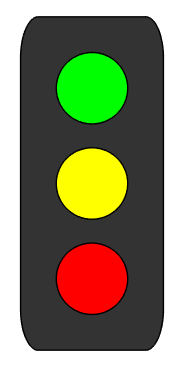                        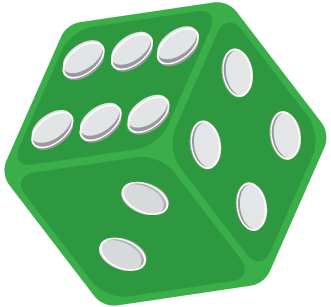

% Choose a value to test this switch statement by causing the code to run
SelectedValue = "red"

SelectedValue = "red"

switch SelectedValue
    case "red"
        disp("When the light is red, you should stop.")
    case "green"
        disp("When the light is green, you should go.")
    case "yellow"
        disp("When the light is yellow, you should slow and stop if you can do so safely.")
end

When the light is red, you should stop.


## **Ứng dụng chi nhánh: Trò chơi hỗn loạn**

Trò chơi Chaos là một bộ quy tắc có thể được áp dụng cho nhiều đa giác khác nhau với kết quả khác nhau. Việc thực hiện này điều tra trò chơi hỗn loạn trên một hình vuông. Bắt đầu tại một điểm được chọn ngẫu nhiên, tại mỗi lần lặp của trò chơi, một điểm mới được chọn là trung bình của điểm hiện tại và đỉnh được chọn ngẫu nhiên của hình vuông. Cuối cùng, sẽ thuận tiện để có thể dễ dàng xác định và so sánh các đỉnh của hình vuông bằng bản đồ được trình bày:

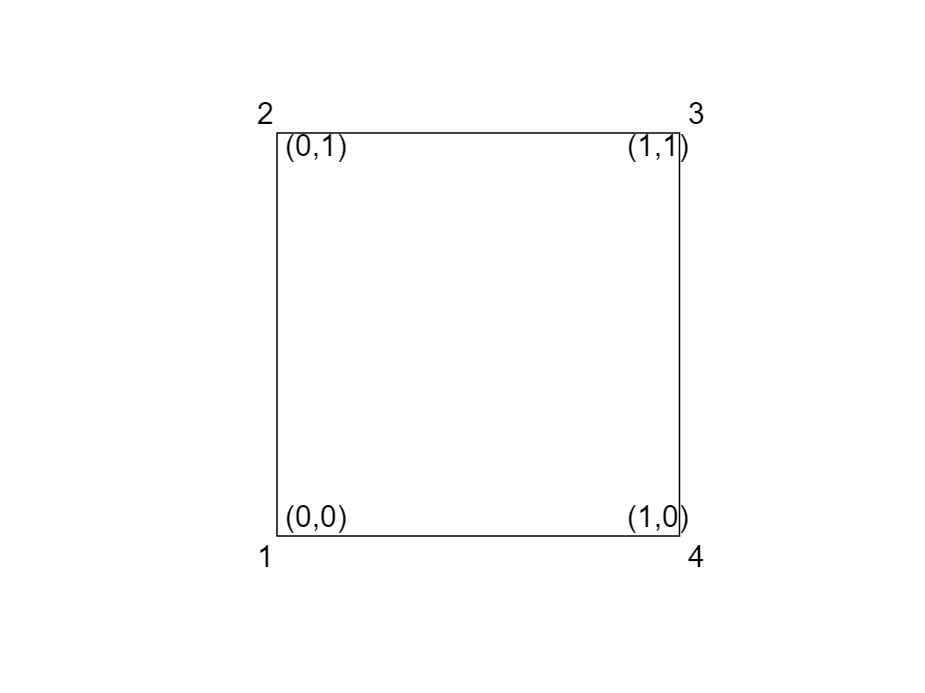

ChaosSquareMap

**Bài tập 3**

Viết câu lệnh chuyển đổi bật biến`Newcorner`với các trường hợp`1, 2, 3,`Và`4`. Nó sẽ đặt giá trị của`Newcoords`Đối với vectơ thích hợp trong mỗi trường hợp, đó là`[0,0]`hoặc`[0,1]`hoặc`[1,1]`hoặc`[1,0]`

% Initialize the value of NewCoords to a result it can never have inside
% the square so it is easy to tell if you update it correctly. Suppress the
% output to prevent clutter.
NewCoords = [-1 -1]; 

% Randomly select a new corner from the set 1, 2, 3, and 4
NewCorner = randi(4,1)      

NewCorner = 3

             
%% Write the switch statement here.

% Run this section to test that the coordinates in NewCoords that you get out 
% are what you expect based on the value of NewCorner

NewCoords

NewCoords =     -1    -1


Lưu kết quả này vì bạn sẽ sử dụng câu lệnh chuyển đổi này một chút sau.

### Bắt đầu trò chơi Chaos

Tiếp tục, để bắt đầu trò chơi Chaos, chúng ta cần chọn điểm bắt đầu. Để đưa ra trường hợp điểm bắt đầu không ảnh hưởng đến các kết quả cuối cùng, hãy chọn điểm bắt đầu đó một cách ngẫu nhiên trong mã bên dưới. Dòng`Điểm khởi đầu = rand ([1 2])`đã bị bỏ lại để bạn có thể theo dõi giá trị ban đầu, nhưng vui lòng thêm một dấu chấm phẩy để triệt tiêu đầu ra bất cứ khi nào bạn tự thuyết phục bản thân rằng mã hoạt động như mong đợi. Trên thực tế, không có vấn đề gì nếu điểm bắt đầu ngẫu nhiên của bạn ở bên trong hình vuông hay không, nhưng sẽ dễ dàng hơn một chút để hình dung những gì đang diễn ra nếu điểm ban đầu có thể nhìn thấy.

  **Thử**. Chạy mã bên dưới nhiều lần và quan sát những gì xảy ra cho các giá trị khác nhau của`Điểm khởi đầu`

StartingPoint = rand([1 2])         % Generate a random starting point in the square

StartingPoint =     0.9575    0.9649


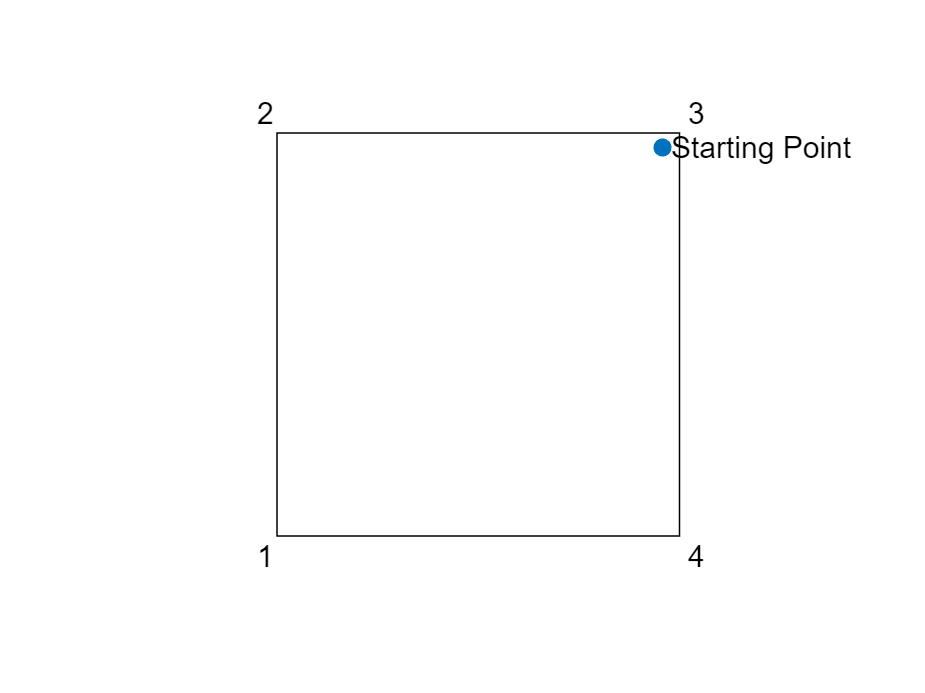

s = StartChaosGame(StartingPoint);

### Thực hiện bước tiếp theo trong trò chơi Chaos

Bước tiếp theo là chọn ngẫu nhiên một trong các đỉnh của hình vuông. Khối mã này chọn một đỉnh theo số nhưng yêu cầu mã bạn đã viết trongBài tập 3Để dịch lựa chọn đó thành các tọa độ có thể được sử dụng để cập nhật trò chơi hỗn loạn bằng cách di chuyển về phía góc đã chọn. Sau khi bạn đã thêm câu lệnh Switch, hãy chạy khối mã này ít nhất 4-5 lần.

NewCorner = randi(4,1)

NewCorner = 1


% Paste the switch statement from Exercise 3 here

s = UpdateChaosGame(s,NewCoords,NewCorner);

## Thêm các bước trò chơi hỗn loạn

Như bạn có thể nhận thấy, nó có một chút mệt mỏi khi thêm các điểm bổ sung bằng cách chạy mã bằng tay mỗi lần. TRONG[Loops.mlx](matlab:open('./Loops.mlx')), bạn sẽ học cách hướng dẫn máy tính tự lặp lại mã.

[Menu menu chính](matlab:open('MainMenu.mlx'))

## Chức năng trợ giúp

#### Chức năng Drawifthentree (N)

Theo liên kết này để trở vềBài tập 2. Có rất nhiều mã trong chức năng này mà bạn có thể không hiểu ngay lập tức, nhưng các ý kiến ��giải thích tại sao mã tồn tại. Bạn nên đọc qua toàn bộ chức năng ít nhất một lần trước khi hoàn thành Bài tập 2.

function DrawIfThenTree(n)
% This function takes an argument n giving the number of options and
% creates an if/then tree depicting choosing between them based on an
% appropriate number of conditions.

%% Code for Exercise 2 goes here


    %% This code generates acceptable trees for values of n > 1

    % Set up the connections between nodes
    TreeNodes = zeros(1,2*n-1);
    TreeNodes(1) = 2;
    for k = 3:2*n-2
        TreeNodes(k) = TreeNodes(k-2)+2;
    end
    TreeNodes(end) = TreeNodes(end-2);

    % Plot the tree and extract the coordinates of the nodes
    treeplot(TreeNodes)
    [x,y] = treelayout(TreeNodes);

    % Set up the labels on the tree

    % preallocate a 2n-1 vector of strings for efficiency
    TreeLabel = strings(1,2*n-1);

    % Label the root node
    TreeLabel(1:2) = ["Option 1","if Condition 1"];

    % Walk through each of the elseif decision points and label them
    for k = 2:n-1
        TreeLabel(2*k-1:2*k) = ["Option "+k, "elseif Condition "+k];
    end

    % Label the final leaf, the outcome if every condition is false
    TreeLabel(2*n-1) = "else Option "+n;
    text(x+.02,y,TreeLabel,"FontWeight","bold")

    % Calculate the locations for the "True" and "False" labels and then
    % print them on the figure
    yOdd = (y(1:2:2*n-2)+y(2:2:2*n-2))/2;
    yEven = (y(2:2:2*n-2)+[y(4:2:2*n-2),y(end)])/2;
    yVals = zeros(1,2*n-2);
    yVals(1:2:2*n-2) = yOdd;
    yVals(2:2:2*n-2) = yEven;
    xSkip = zeros(size(yVals));
    xSkip(1:2:end) = -0.07;
    % Note: The choice of 0.03*n as the initial even xSkip value is an approximation
    %       It works well for n in [2,6], but then it begins to fail.
    xSkip(2:2:end) = linspace(0.03*n,0.02,(n-1));
    xVals = repmat("True",size(xSkip));
    xVals(2:2:end) = "False";
    text(x(1:end-1)+diff(x)/2+xSkip,yVals,xVals,"FontSize",8,"Color","blue")

    % This tree is much easier to read without a visible axis
    axis off
    % And zoomed in to fill the available space
    xlim([max(.1,.5-n/10) min(1,.6+n/10)])
    ylim([max(.1,.5-n/10) min(.9,.5+n/10)])
    %% This is the end of the tree-generation code for n > 1

%% Code for Exercise 2 goes here, too

%%

end


#### Mã tạo hình ảnh

Mã này hoàn toàn là thông tin. Nhiều số liệu mà bạn gặp phải trong suốt các tập lệnh này được tạo trong MATLAB. Dưới đây là mã tạo ra một số hình ảnh được sử dụng trong tập lệnh này như đèn giao thông.

function Trafficlight %#ok<DEFNU> 
% This function generates an image of a traffic light oriented vertically
% with a red light above a yellow light above a green light.

figure

% With Curvature of [0 0] these commands would give rectangles, with
% positive values of Curvature the corners are rounded
rectangle("Position",[0 0 3 7],"Curvature",[.25 .25],"FaceColor",[.2 .2 .2])
rectangle("Position",[.75 4.75 1.5 1.5],"Curvature",[1 1],"FaceColor","red")
rectangle("Position",[.75 .75 1.5 1.5],"Curvature",[1 1],"FaceColor","green")
rectangle("Position",[.75 2.75 1.5 1.5],"Curvature",[1 1],"FaceColor","yellow")
ylim([-.1 7.1])
xlim([-2.1 5.1])

% This figure is prettier when drawn with equal measurements along both the
% x and y axes, but without the axes showing
axis square off
end

function ChaosSquare
% This function generates the annotated image of the square board for the
% Chaos Game where each corner is labeled with only its integer label

figure
rectangle("Position",[0 0 1 1],"Curvature",[0 0])
xlim([-0.2,1.2])
ylim([-0.2,1.2])
text(-0.05,-0.05,"1")
text(-0.05,1.05,"2")
text(1.02,1.05,"3")
text(1.02,-0.05,"4")

% This figure is prettier when drawn with equal measurements along both the
% x and y axes, but without the axes showing
axis square off
end

function Data = StartChaosGame(StartingPoint)
% The function StartChaosGame takes one input value, the StartingPoint
% coordinates and it returns one value, data, which contains information
% about the structure of the game and how to draw it

ChaosSquare                         % Draw the board on which this game will be played
hold on                             % Continue drawing on this figure

% Graph and label the starting point. Note the coordinate shift by 0.02 in
% the x direction for readability. 
s = scatter(StartingPoint(1),StartingPoint(2),"o","filled");
t = text(s.XData+0.02,s.YData,"Starting Point");
hold off
c = copyobj(s,s.Parent);   % Create a scatter plot object to identify the selected corner
l = copyobj(s,s.Parent);   % Create a scatter plot object to identify the last point

% Save the information about the game to be used in updateChaosGame later
Data = struct('s',s,'t',t,'c',c,'l',l);
end

function Data = UpdateChaosGame(Data,NewCoords,NewCorner)
% The function UpdateChaosGame takes two inputs, the data generated by
% StartChaosGame and the coordinates NewCoords identifying the newly chosen vertex
% It returns an updated value of data containing information about the
% current state of the game

if all(NewCoords == [-1 -1])
    % This is the default value. You need to update the code before you get
    % here. Post a warning if it isn't updated at this point.
    warning("These coordinates are outside the square." + newline ...
        +"Did you complete the switch statement in Exercise 3?")
    % Exit the function because the code is not ready
    return
end

% In the annotation space coordinates, the corners of the square have
% x = .3 or x = .735 and y = .23 or y = .81. Shift the coordinates to
% account for the transformation by (x-coords)*(.735-.3)+.3 and
% (y-coords)*(.81-.23)+.23

annotation("arrow",[Data.s.XData(end) (Data.s.XData(end)+NewCoords(1))/2]*.435+.3, ...
    [Data.s.YData(end) (Data.s.YData(end)+NewCoords(2))/2]*.58+.23)

% Add the new points to the scatter plot
Data.l.XData = Data.s.XData(end);
Data.l.YData = Data.s.YData(end);
Data.l.MarkerFaceColor = "g";

% Determine how to shift the text to stay away from the new arrow. 
switch NewCorner
    case 1
        xShift = 0.03;
        yShift = 0.06;
    case 2
        xShift = 0.03;
        yShift = -0.06;
    case 3
        xShift = 0.03;
        yShift = -0.06;
    case 4
        xShift = 0.03;
        yShift = 0.06;
end

% Update the text printed next to the data points based on how many steps
% into the game you currently are. After the third move, assume the player
% understands the structure and doesn't need additional labels cluttering
% the game board
switch length(Data.s.XData)
    case 1
        Data.t.String = ["From here move halfway" "towards the corner"];
        Data.t.Position = [Data.s.XData(end) Data.s.YData(end) 0] + [xShift yShift 0];
    case 2
        Data.t.String = "Now start here";
        Data.t.Position = [Data.s.XData(end) Data.s.YData(end) 0] + [xShift yShift 0];
    case 3
        Data.t.String = "And now here, etc.";
        Data.t.Position = [Data.s.XData(end) Data.s.YData(end) 0] + [xShift yShift 0];
    otherwise
        Data.t.String = "";
end

% Add the new information to the data structure
Data.s.XData = [Data.s.XData (Data.s.XData(end)+NewCoords(1))/2];
Data.s.YData = [Data.s.YData (Data.s.YData(end)+NewCoords(2))/2];
Data.c.XData = NewCoords(1);
Data.c.YData = NewCoords(2);
Data.c.MarkerFaceColor = "r";
end

function ChaosSquareMap
% This function generates the annotated image of the square board for the
% Chaos Game where each corner is labeled with both its integer label and
% its coordinate values for reference

figure
rectangle("Position",[0 0 1 1],"Curvature",[0 0])

% Label each corner with its corresponding value
text(-0.05,-0.05,"1")
text(-0.05,1.05,"2")
text(1.02,1.05,"3")
text(1.02,-0.05,"4")

% Label each corner with its corresponding coordinates
text(.02,.05,"(0,0)")
text(.02,.97,"(0,1)")
text(.87,.97,"(1,1)")
text(.87,.05,"(1,0)")

% Set the range and domain for the viewing window
xlim([-0.2,1.2])
ylim([-0.2,1.2])

% This figure is prettier when drawn with equal measurements along both the
% x and y axes, but without the axes showing
axis square off
end
